### Parsing ROSBAGS

**1.Create an empty directory as a workspace and have this mlx. script along with the***** extractData.m***** function within the workspace. Provide path to the directory that contains all the rosbags.**

clc
clear


%Slope
%abs_path = 'C:\Users\asalvi\Downloads\bags0\'; %  <-------- Path to ROSBAGS directory on your system

%Flat Grass
%abs_path = 'C:\Users\asalvi\Documents\Ameya_workspace\MixModelsIK\LrgModelBag\bags_OneM\';
abs_path = 'C:\Users\asalvi\Downloads\bsln_14_08\';

strcat(abs_path,'*.*');

Files=dir(strcat(abs_path,'*.*'));
for k=1:length(Files)
   FileNames=Files(k).name
end

FileNames = '.'

FileNames = '..'

FileNames = 'bsln_2024-08-14-08-37-55.bag'

FileNames = 'bslnb_2024-08-14-08-42-49.bag'

FileNames = 'coneb_2024-08-14-08-46-53.bag'

FileNames = 'conec_2024-08-14-08-48-14.bag'

FileNames = 'idx1_2024-08-14-08-55-22.bag'

FileNames = 'idx2_2024-08-14-08-57-22.bag'

FileNames = 'idx3_2024-08-14-08-59-28.bag'

FileNames = 'idx4_2024-08-14-09-02-06.bag'

**2. Parse all the rosbags and save them as a matlab readable structure. **

**Once the bags are converted to structure, see what all are the available topics.**

for k=1:length(Files)-2
   bag(k)= rosbag(strcat(abs_path,Files(k+2).name));
end

         at line 278 in B:\3p\derived\win64\ros1\src\geometry2\tf2\src\buffer_core.cpp
         at line 278 in B:\3p\derived\win64\ros1\src\geometry2\tf2\src\buffer_core.cpp
         at line 278 in B:\3p\derived\win64\ros1\src\geometry2\tf2\src\buffer_core.cpp
         at line 278 in B:\3p\derived\win64\ros1\src\geometry2\tf2\src\buffer_core.cpp


% Print available topics:
bag(1, 1).AvailableTopics

ans = 58×3 table
                                                         NumMessages                 MessageType                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        MessageDefinition                           

**3. You can choose which of the available topics you want to extract. Set the variable as '1' for all the topics you want to be extracted.**

% chose topics out of available topics (true =1 , false =0)

which_topic.tf = 1;
which_topic.gps_head = 1;
which_topic.gps_pos = 1;
which_topic.imu = 1;
which_topic.imu_fil = 1 ;
which_topic.js = 1;
which_topic.cmd_vel = 1;
which_topic.odom = 1;
which_topic.axis_camera = 0;


**4. Parse the topics. A folders called 'imgs_bag_no' will be created and .jpg format images will be stored in that folder if you choos *****axis_camera***** topic as true.**

%for k = 2
origin = [34.8146 -82.3249 240.0519]; 
for k=1:length(Files)-2
   sensor(k) = extractData(bag(k),which_topic,pwd,k,origin);
   %k
end


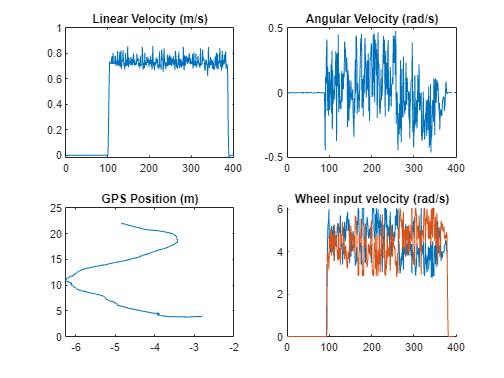

k_ = 2;

figure

subplot(2,2,1)
plot(sensor(k_).data.odom_VelLinX)
title('Linear Velocity (m/s)')

subplot(2,2,2)
plot(sensor(k_).data.IMU_fil_AngZ)
title('Angular Velocity (rad/s)')

subplot(2,2,3)
plot(sensor(k_).data.enu_x,sensor(k_).data.enu_y)
title('GPS Position (m)')

subplot(2,2,4)
hold on
plot(sensor(k_).data.joint_states(1,:))
plot(sensor(k_).data.joint_states(2,:))
title('Wheel input velocity (rad/s)')

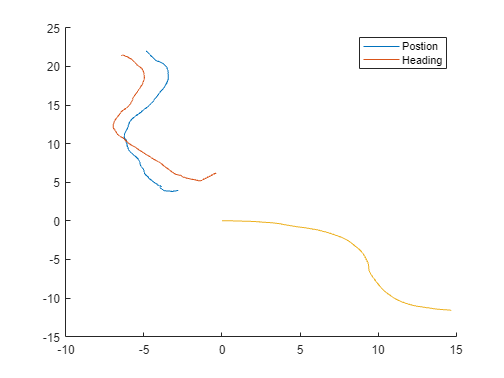


figure
hold on
%plot(sensor(1).data.enu_x,sensor(1).data.enu_y)
plot(sensor(k_).data.enu_x,sensor(k_).data.enu_y)
plot(sensor(k_).data.enu_head_x,sensor(k_).data.enu_head_y)
plot(sensor(k_).data.odom_PosX,sensor(k_).data.odom_PosY)
legend('Postion','Heading')

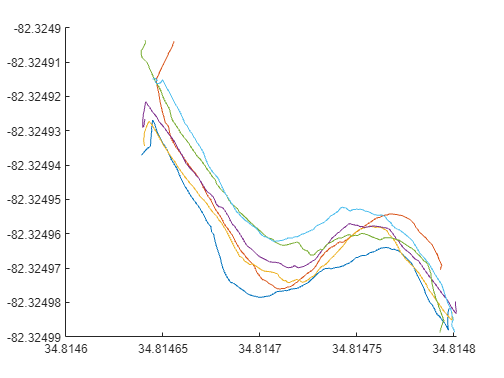


figure
hold on
plot(sensor(k_-1).data.gps_head_Lat,sensor(k_-1).data.gps_head_Long)
plot(sensor(k_).data.gps_head_Lat,sensor(k_).data.gps_head_Long)
plot(sensor(k_+3).data.gps_head_Lat,sensor(k_+3).data.gps_head_Long)
plot(sensor(k_+4).data.gps_head_Lat,sensor(k_+4).data.gps_head_Long)
plot(sensor(k_+5).data.gps_head_Lat,sensor(k_+5).data.gps_head_Long)
plot(sensor(k_+6).data.gps_head_Lat,sensor(k_+6).data.gps_head_Long)

%plot(sensor(k_+1).data.gpsLat,sensor(k_+1).data.gpsLong)
%plot(sensor(k_+2).data.gpsLat,sensor(k_+2).data.gpsLong)


% figure
% hold on
% %plot(sensor(1).data.enu_x,sensor(1).data.enu_y)
% plot(sensor(k_+2).data.enu_x,sensor(k_+2).data.enu_y)
% plot(sensor(k_+2).data.enu_head_x,sensor(k_+2).data.enu_head_y)
% legend('Postion','Heading')
%plot(mean(sensor(k_).data.enu_x,sensor(k_).data.enu_head_x),mean(sensor(k_).data.enu_y,sensor(k_).data.enu_head_y))


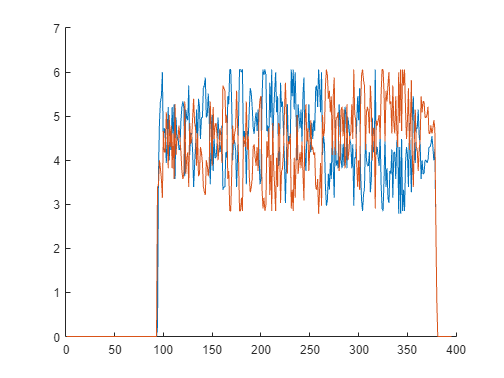

figure
k_=2;
hold on
plot(sensor(k_).data.joint_states(1,:))
plot(sensor(k_).data.joint_states(2,:))

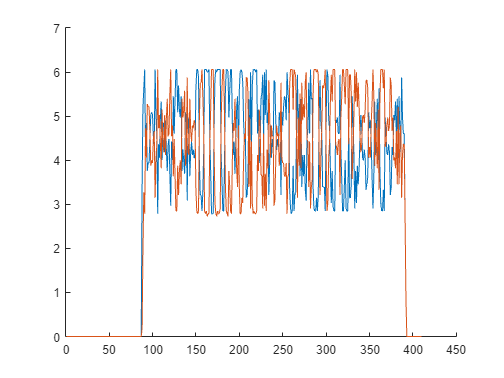


figure
k_=5;
hold on
plot(sensor(k_).data.joint_states(1,:))
plot(sensor(k_).data.joint_states(2,:))

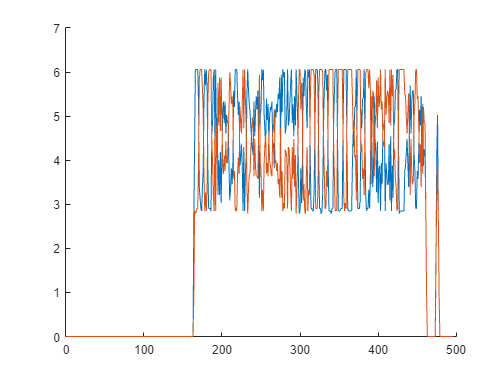


figure
k_=8;
hold on
plot(sensor(k_).data.joint_states(1,:))
plot(sensor(k_).data.joint_states(2,:))

Sync_topics.odom_VelLinX = 1;
Sync_topics.gps = 1;
Sync_topics.gps_head = 1;
Sync_topics.IMU_fil_AngZ = 1;
Sync_topics.odom_pos = 1;

TSyn = timeSync(sensor,k,Sync_topics);


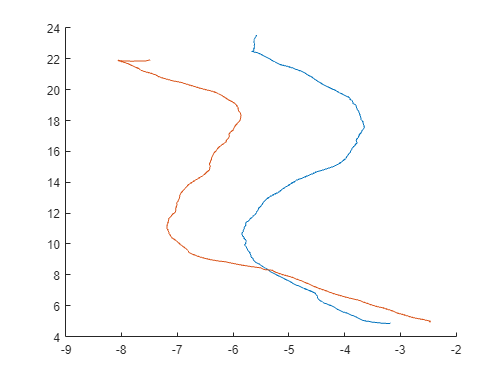

k_t = find(sensor(1).data.joint_states(1,:)>0);

figure
hold on
plot(TSyn(1).data.enu_x(k_t:end),TSyn(1).data.enu_y(k_t:end))
plot(TSyn(1).data.enu_x_head(k_t:end),TSyn(1).data.enu_y_head(k_t:end))

%plot(TSyn(1).data.pos_x(k_t:end),TSyn(1).data.pos_y(k_t:end))


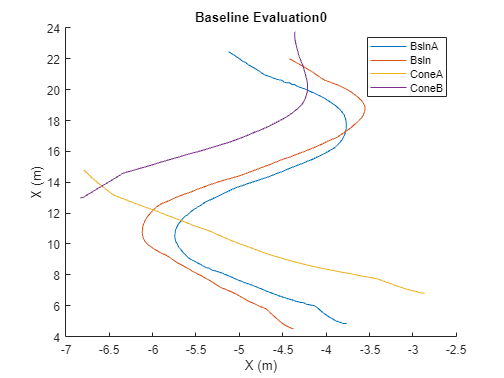


%start = 0;
%stop = 
figure
hold on
title('Baseline Evaluation0')

for i = [1,2,3,4]
    k_t = find(sensor(i).data.joint_states(1,:)>0);
    A = mean([TSyn(i).data.enu_x(k_t);TSyn(i).data.enu_x(k_t)]);
    B = mean([TSyn(i).data.enu_y(k_t);TSyn(i).data.enu_y(k_t)]);
    idx = 1:length(A);
    A_ = movmean(A(idx),50);
    B_ = movmean(B(idx),50);
    %plot(A_ - A_(1),B_ - B_(1))
    plot(A_,B)
end


legend('BslnA','Bsln','ConeA','ConeB')
xlabel('X (m)')
ylabel('X (m)')

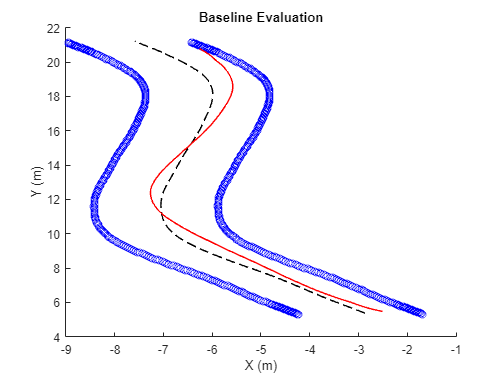

%start = 0;
%stop = 
figure
hold on
title('Baseline Evaluation')

%for i = [1,2,3,4]
i = 1;
k_t = find(sensor(i).data.joint_states(1,:)>0);
A = mean([TSyn(i).data.enu_x_head(k_t);TSyn(i).data.enu_x_head(k_t)]);
B = mean([TSyn(i).data.enu_y_head(k_t);TSyn(i).data.enu_y_head(k_t)]);
idx = 1:length(A);
A_ = movmean(A(idx),50);
B_ = movmean(B(idx),50);
%plot(A_ - A_(1),B_ - B_(1),'--k','LineWidth',1.2)
plot(A_,B_,'--k','LineWidth',1.2)

i = 1;
k_t = find(sensor(i).data.joint_states(1,:)>0);
A = mean([TSyn(i).data.enu_x_head(k_t);TSyn(i).data.enu_x_head(k_t)]);
B = mean([TSyn(i).data.enu_y_head(k_t);TSyn(i).data.enu_y_head(k_t)]);
idx = 1:length(A);
A_ = movmean(A(idx),50);
B_ = movmean(B(idx),50);
%plot((0.5*rand-0.5)*0.001*length(A_) + (A_ - A_(1)-0.85),(0.5*rand-0.5)*0.001*length(B_) + (B_ - B_(1)),'.')
plot((0.5*rand-0.5)*0.001*length(A_) + (A_ -1.25),(0.5*rand-0.5)*0.001*length(B_) + (B_ ),'bo')

i = 1;
k_t = find(sensor(i).data.joint_states(1,:)>0);
A = mean([TSyn(i).data.enu_x_head(k_t);TSyn(i).data.enu_x_head(k_t)]);
B = mean([TSyn(i).data.enu_y_head(k_t);TSyn(i).data.enu_y_head(k_t)]);
idx = 1:length(A);
A_ = movmean(A(idx),50);
B_ = movmean(B(idx),50);
%plot((0.5*rand-0.5)*0.001*length(A_) + (A_ - A_(1)+0.85),(0.5*rand-0.5)*0.001*length(B_) + (B_ - B_(1)),'.')
plot((0.5*rand-0.5)*0.001*length(A_) + (A_ +1.25),(0.5*rand-0.5)*0.001*length(B_) + (B_ ),'bo')

i = 2;
k_t = find(sensor(i).data.joint_states(1,:)>0);
A = mean([TSyn(i).data.enu_x_head(k_t);TSyn(i).data.enu_x_head(k_t)]);
B = mean([TSyn(i).data.enu_y_head(k_t);TSyn(i).data.enu_y_head(k_t)]);
idx = 1:length(A);
A_ = movmean(A(idx),50);
B_ = movmean(B(idx),50);
%plot(A_ - A_(1)-0.1,B_ - B_(1),'r','LineWidth',1.2)
plot(A_-0.5,B_,'r','LineWidth',1.2)

%end

%legend('Lane Centre','Bsln','ConeA','ConeB')
xlabel('X (m)')
ylabel('Y (m)')

### Plot Baseline Trajectory



FS = 18;



f1 = figure('Position', [100, 100, 2000, 500],'color','w') % [left, bottom, width, height]

f1 =   Figure (10) with properties:

      Number: 10
        Name: ''
       Color: [1 1 1]
    Position: [100 100 2000 500]
       Units: 'pixels'

  Show all properties


%f1 = figure('color','w')
ax = gca;
ax.FontName= 'Times New Roman';
ax.FontSize = FS;

box on
hold on
title('Policy Deployment','FontWeight', 'bold','Interpreter','latex','FontSize',FS)

%for i = [1,2,3,4]
i = 1;
k_t = find(sensor(i).data.joint_states(1,:)>0);
A = mean([TSyn(i).data.enu_x_head(k_t);TSyn(i).data.enu_x_head(k_t)]);
B = mean([TSyn(i).data.enu_y_head(k_t);TSyn(i).data.enu_y_head(k_t)]);
idx = 1:length(A);
A_ = movmean(A(idx),50);
B_ = movmean(B(idx),50);
%plot(A_ - A_(1),B_ - B_(1),'--k','LineWidth',1.2)
plot(B_, -A_, '--k', 'LineWidth', 1.5)
curveA = [B_;-A_];

d = pdist(curveA, 'euclidean');
% Sum up the distances to get the total curve length
curve_length = sum(d);


i = 1;
k_t = find(sensor(i).data.joint_states(1,:)>0);
A = mean([TSyn(i).data.enu_x_head(k_t);TSyn(i).data.enu_x_head(k_t)]);
B = mean([TSyn(i).data.enu_y_head(k_t);TSyn(i).data.enu_y_head(k_t)]);
idx = 1:length(A);
A_ = movmean(A(idx),50);
B_ = movmean(B(idx),50);
%plot((0.5*rand-0.5)*0.001*length(A_) + (A_ - A_(1)-0.85),(0.5*rand-0.5)*0.001*length(B_) + (B_ - B_(1)),'.')
plot(((0.5*rand-0.5)*0.001*length(B_) + B_ ), -((0.5*rand-0.5)*0.001*length(A_) + (A_ - 1.25)),'bo')


i = 1;
k_t = find(sensor(i).data.joint_states(1,:)>0);
A = mean([TSyn(i).data.enu_x_head(k_t);TSyn(i).data.enu_x_head(k_t)]);
B = mean([TSyn(i).data.enu_y_head(k_t);TSyn(i).data.enu_y_head(k_t)]);
idx = 1:length(A);
A_ = movmean(A(idx),50);
B_ = movmean(B(idx),50);
%plot((0.5*rand-0.5)*0.001*length(A_) + (A_ - A_(1)+0.85),(0.5*rand-0.5)*0.001*length(B_) + (B_ - B_(1)),'.')
plot(((0.5*rand-0.5)*0.001*length(B_) + B_ ), -((0.5*rand-0.5)*0.001*length(A_) + (A_ + 1.25)),'bo')

i = 2;
k_t = find(sensor(i).data.joint_states(1,:)>0);
A = mean([TSyn(i).data.enu_x_head(k_t);TSyn(i).data.enu_x_head(k_t)]);
B = mean([TSyn(i).data.enu_y_head(k_t);TSyn(i).data.enu_y_head(k_t)]);
idx = 1:length(A);
A_ = movmean(A(idx),50);
B_ = movmean(B(idx),50);
%plot(A_ - A_(1)-0.1,B_ - B_(1),'r','LineWidth',1.2)
plot(B_, -(A_-1),'r','LineWidth',1.5)
Bg = B_(1);
Ag = (A_(1) - 0.5)

Ag = -2.5104

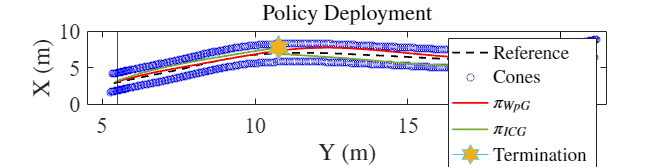

curveB = [B_;-A_];


i = 3;
k_t = find(sensor(i).data.joint_states(1,:)>0);
A = mean([TSyn(i).data.enu_x_head(k_t);TSyn(i).data.enu_x_head(k_t)]);
B = mean([TSyn(i).data.enu_y_head(k_t);TSyn(i).data.enu_y_head(k_t)]);
idx = 1:length(A);
A_ = movmean(A(idx),50);
B_ = movmean(B(idx),50);
%plot(A_ - A_(1)-0.1,B_ - B_(1),'r','LineWidth',1.2)
plot(B_ + 1, -A_ - 0.5 + 3,'color',[0.4660 0.6740 0.1880],'LineWidth',1.5)
plot(B_(end) + 1, -A_(end) - 0.5 + 3,'Marker','hexagram','MarkerSize',20,'MarkerFaceColor',[0.9290 0.6940 0.1250])
%curveC1 = [B_+1;-A_-0.5+3];
curveC1 = [B_;-A_];

i = 4;
k_t = find(sensor(i).data.joint_states(1,:)>0);
A = mean([TSyn(i).data.enu_x_head(k_t);TSyn(i).data.enu_x_head(k_t)]);
B = mean([TSyn(i).data.enu_y_head(k_t);TSyn(i).data.enu_y_head(k_t)]);
idx = 1:length(A);
A_ = movmean(A(idx),50);
B_ = movmean(B(idx),50);
%plot(A_ - A_(1)-0.1,B_ - B_(1),'r','LineWidth',1.2)
plot(B_ + 0.5, -A_-0.5 + 3,'color',[0.4660 0.6740 0.1880],'LineWidth',1.5)
plot(B_(end) + 0.5, -A_(end)-0.5 + 3,'Marker','hexagram','MarkerSize',20,'MarkerFaceColor',[0.9290 0.6940 0.1250])
curveC2 = [B_+0.5;-A_-0.5+3];
%curveC = [curveC1(1,:),B_ + 0.5;curveC1(2,:),-A_-0.5 + 3];
curveC = [curveC1(1,:),B_;curveC1(2,:),-A_];

xline(5.5,'k')
xline(20,'k')

%end
xlim([4.5,21.5])

%legend('Lane Centre','Bsln','ConeA','ConeB')
xlabel('Y (m)','FontWeight', 'bold','Interpreter','latex')
ylabel('X (m)','FontWeight', 'bold','Interpreter','latex')

legend('Reference','Cones','','$ \pi_{WpG}$','$ \pi_{ICG}$','Termination','Location','southeast','Interpreter','latex')


%set(gcf, 'PaperUnits', 'inches');
%set(gcf, 'PaperPosition', [0 0 3.5 2.5]);  % For single-column width
%set(gcf, 'PaperPosition', [0 0 7.16 2]);  % For double-column width

%print(f1,'DeployBsln','-depsc')


FS = 18;

%f1 = figure('Color','white')
f1 = figure('Position', [100, 100, 1000, 350],'color','w') % [left, bottom, width, height]

f1 =   Figure (11) with properties:

      Number: 11
        Name: ''
       Color: [1 1 1]
    Position: [100 100 1000 350]
       Units: 'pixels'

  Show all properties



%subplot(2,1,1)
ax = gca;
ax.FontName= 'Times New Roman';
ax.FontSize = FS;

title('Body Velocity (${}^{B}V$) Tracking','FontWeight', 'bold','Interpreter','latex','FontSize',FS)
hold on

i = 2;
k_t = find(sensor(i).data.joint_states(1,:)>0);
plot(curveB(1,:),movmean(TSyn(i).data.odom_VelLinX(k_t),5),'r','LineWidth',1.5)
mean(TSyn(2).data.odom_VelLinX(k_t))

ans = 0.7265


i = 3;
k_t = find(sensor(i).data.joint_states(1,:)>0);
plot(curveC1(1,:),movmean(TSyn(i).data.odom_VelLinX(k_t),5),'color',[0.4660 0.6740 0.1880],'LineWidth',1.5)

i = 4;
k_t = find(sensor(i).data.joint_states(1,:)>0);
plot(curveC2(1,:),movmean(TSyn(i).data.odom_VelLinX(k_t),5),'color',[0.4660 0.6740 0.1880],'LineWidth',1.5)
mean(TSyn(4).data.odom_VelLinX(k_t))

ans = 0.7144

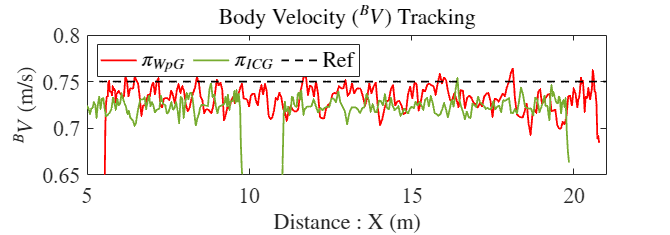


plot(curveA(1,:),0.75*ones(length(curveA(1,:)),1),'--k','LineWidth',1.5)

legend('$ \pi_{WpG}$', '$ \pi_{ICG}$','','Ref','Location','northwest','Orientation','horizontal','Interpreter','latex','FontSize',FS)
ylim([0.65,0.8])
xlim([5 21])
xlabel('Distance : X (m)','Interpreter','latex','FontSize',FS)
ylabel('${}^{B}V$ (m/s)','Interpreter','latex','FontSize',FS)

box on


%print(f1,'DeployBslnVel','-depsc')

%mean(TSyn(2).data.odom_VelLinX(k_t))
%mean(TSyn(4).data.odom_VelLinX(k_t))

[meanErr, varErr, errors] = compareCurves(curveA,curveB)

meanErr = 0.7318

varErr = 0.0925

errors =     0.8643    0.8532    0.8421    0.8311    0.8204    0.8110    0.8032    0.7978    0.7934    0.7906    0.7883    0.7864    0.7843    0.7835    0.7833    0.7793    0.7744    0.7701    0.7660    0.7612    0.7571    0.7537    0.7503    0.7468    0.7434    0.7403    0.7375    0.7347    0.7318    0.7296    0.7274    0.7256    0.7247    0.7241    0.7236    0.7236    0.7236    0.7242    0.7255    0.7268    0.7277    0.7280    0.7285    0.7294    0.7314    0.7344    0.7380    0.7425    0.7472    0.7524


[meanErr2, varErr2, errors2] = compareCurves(curveA,curveC)

meanErr2 = 3.0898

varErr2 = 0.4360

errors2 =     2.4937    2.4890    2.4845    2.4799    2.4754    2.4710    2.4667    2.4630    2.4597    2.4568    2.4541    2.4516    2.4492    2.4469    2.4447    2.4427    2.4399    2.4370    2.4343    2.4316    2.4285    2.4256    2.4227    2.4199    2.4170    2.4141    2.4113    2.4086    2.4059    2.4034    2.4009    2.3985    2.3962    2.3942    2.3923    2.3906    2.3891    2.3875    2.3859    2.3843    2.3833    2.3823    2.3816    2.3806    2.3800    2.3796    2.3792    2.3791    2.3792    2.3795


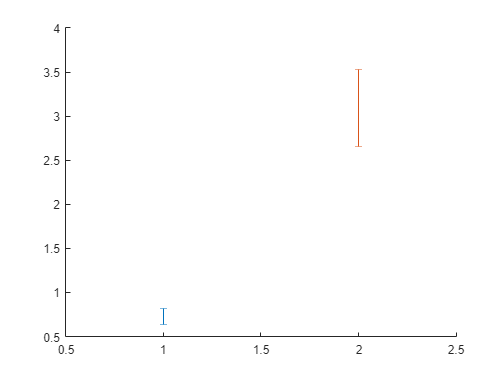


figure
hold on
errorbar(1,meanErr,varErr)
errorbar(2,meanErr2,varErr2)
xlim([0.5 2.5])


% Display the results
disp(['Mean Error: ', num2str(meanErr)]);

Mean Error: 0.73176


disp(['Variance Error: ', num2str(varErr)]);

Variance Error: 0.092464



FS = 16

FS = 16

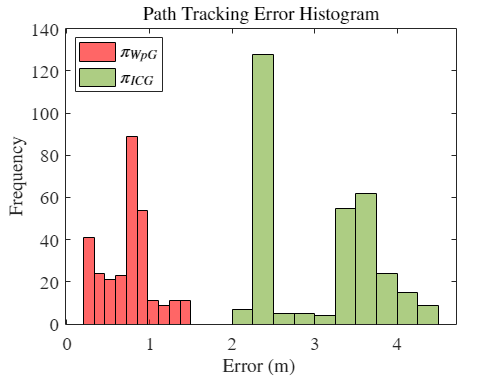

% Plot the histogram of errors
f1 = figure('Color','white');
ax = gca;
ax.FontName= 'Times New Roman';
ax.FontSize = FS;
hold on
histogram(errors, 10,'FaceColor','r'); % Adjust the number of bins as needed
histogram(errors2, 10,'FaceColor',[0.4660 0.6740 0.1880]); % Adjust the number of bins as needed
title('Path Tracking Error Histogram','FontWeight', 'bold','Interpreter','latex','FontSize',FS);
xlabel('Error (m) ','FontWeight', 'bold','Interpreter','latex','FontSize',FS);
ylabel('Frequency','FontWeight', 'bold','Interpreter','latex','FontSize',FS);
box on
legend('$ \pi_{WpG}$', '$ \pi_{ICG}$','Location','northwest','FontSize',FS,'Interpreter','latex')

%print(f1,'BslnHisto','-depsc')


FS = 18;
%figure
f1 = figure('Position', [100, 100, 1000, 350],'color','w') % [left, bottom, width, height]

f1 =   Figure (39) with properties:

      Number: 39
        Name: ''
       Color: [1 1 1]
    Position: [100 100 1000 350]
       Units: 'pixels'

  Show all properties


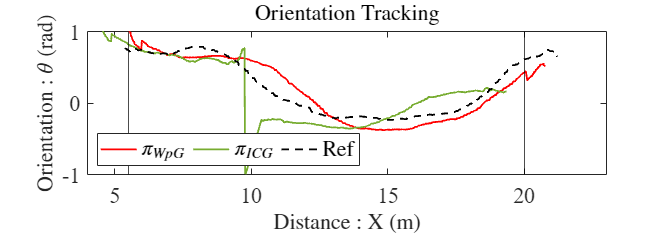

%subplot(2,1,2)
ax = gca;
ax.FontName= 'Times New Roman';
ax.FontSize = FS;

title('Orientation Tracking','FontWeight', 'bold','Interpreter','latex','FontSize',FS)
hold on

headingA = headingFromXY(curveA');
headingB = headingFromXY(curveB');
headingC = headingFromXY(curveC');

plot(curveB(1,:),headingB,'r','LineWidth',1.5)
plot(curveC(1,:),headingC,'color',[0.4660 0.6740 0.1880],'LineWidth',1.5)
plot(curveA(1,:),headingA,'--k','LineWidth',1.5)

xline(5.5,'k')
xline(20,'k')

legend('$ \pi_{WpG}$', '$ \pi_{ICG}$','Ref','Location','southwest','Orientation','horizontal','Interpreter','latex','FontSize',FS)
ylim([-1,1])
xlim([4 23])
xlabel('Distance : X (m)','Interpreter','latex','FontSize',FS)
ylabel('Orientation : $\theta$ (rad)','Interpreter','latex','FontSize',FS)

box on


%print(f1,'DeployBslnPose','-depsc')

[meanOrErr, varOrErr, Orerrors] = compareCurves([curveA(1,:);headingA'],[curveB(1,:);headingB'])

meanOrErr = 0.2032

varOrErr = 0.0034

Orerrors =     0.2817    0.2890    0.2689    0.2403    0.2064    0.1472    0.1094    0.0784    0.0571    0.0504    0.0554    0.0333    0.0356    0.0778    0.1456    0.2126    0.2047    0.2011    0.1969    0.1893    0.1900    0.1852    0.1856    0.1822    0.1826    0.1787    0.1763    0.1753    0.1751    0.1753    0.1743    0.1709    0.1746    0.1716    0.1711    0.1707    0.1699    0.1700    0.1840    0.1877    0.2045    0.2091    0.2128    0.2151    0.2166    0.2205    0.2240    0.2272    0.2269    0.2258


[meanOrErr2, varOrErr2, Orerrors2] = compareCurves([curveA(1,:);headingA'],[curveC(1,:);headingC'])

meanOrErr2 = 2.3762

varOrErr2 = 0.9540

Orerrors2 =     1.0222    1.0343    1.0416    1.0520    1.0584    1.0586    1.0558    1.0627    1.0660    1.0786    1.0809    1.0801    1.1012    1.1507    1.1845    1.1844    1.1823    1.1829    1.1832    1.1839    1.1842    1.1854    1.1860    1.1869    1.1875    1.1888    1.1920    1.1921    1.1931    1.1932    1.1933    1.1948    1.1919    1.1907    1.1919    1.1919    1.1903    1.1900    1.1890    1.1877    1.1864    1.1879    1.1867    1.1868    1.1868    1.1869    1.1868    1.1868    1.1887    1.1888


### Plot Comparison Trajectories


colors = [
    1 0 0;
    0.9290 0.6940 0.1250;
    0.4940 0.1840 0.5560;
    0.4660 0.6740 0.1880;
    0.3010 0.7450 0.9330;
];

clear curveA curveB curveC

FS = 18;

%ax = gca;
%ax.FontName= 'Times New Roman';
%ax.FontSize = FS;

%box on
%hold on
%title('Policy Deployment','FontWeight', 'bold','Interpreter','latex','FontSize',FS)


f1 = figure('Position', [100, 100, 2000, 500],'color','w') % [left, bottom, width, height]

f1 =   Figure (40) with properties:

      Number: 40
        Name: ''
       Color: [1 1 1]
    Position: [100 100 2000 500]
       Units: 'pixels'

  Show all properties


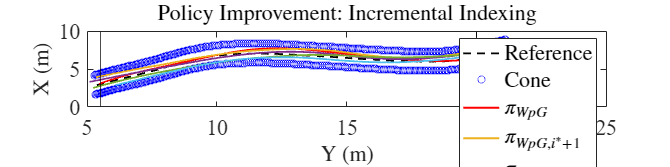

ax = gca;
ax.FontName= 'Times New Roman';
ax.FontSize = FS;

box on
hold on
title('Policy Improvement: Incremental Indexing','Interpreter','latex','FontSize',FS)

i = 1;
k_t = find(sensor(i).data.joint_states(1,:)>0);
A = mean([TSyn(i).data.enu_x_head(k_t);TSyn(i).data.enu_x_head(k_t)]);
B = mean([TSyn(i).data.enu_y_head(k_t);TSyn(i).data.enu_y_head(k_t)]);
idx = 1:length(A);
A_ = movmean(A(idx),50);
B_ = movmean(B(idx),50);
%plot(A_ ,B_ ,'--k','LineWidth',1.5)
plot(B_, -(A_),'--k','LineWidth',1.5)
Bg = B_(1);
Ag = (A_(1) - 0.5);
curveA = [B_;-A_];

i = 1;
k_t = find(sensor(i).data.joint_states(1,:)>0);
A = mean([TSyn(i).data.enu_x_head(k_t);TSyn(i).data.enu_x_head(k_t)]);
B = mean([TSyn(i).data.enu_y_head(k_t);TSyn(i).data.enu_y_head(k_t)]);
idx = 1:length(A);
A_ = movmean(A(idx),50);
B_ = movmean(B(idx),50);
%plot((0.5*rand-0.5)*0.001*length(A_) + (A_ - A_(1)-0.85),(0.5*rand-0.5)*0.001*length(B_) + (B_ - B_(1)),'.')
plot(((0.5*rand-0.5)*0.001*length(B_) + B_ ), -((0.5*rand-0.5)*0.001*length(A_) + (A_ - 1.25)),'bo')


i = 1;
k_t = find(sensor(i).data.joint_states(1,:)>0);
A = mean([TSyn(i).data.enu_x_head(k_t);TSyn(i).data.enu_x_head(k_t)]);
B = mean([TSyn(i).data.enu_y_head(k_t);TSyn(i).data.enu_y_head(k_t)]);
idx = 1:length(A);
A_ = movmean(A(idx),50);
B_ = movmean(B(idx),50);
%plot((0.5*rand-0.5)*0.001*length(A_) + (A_ - A_(1)+0.85),(0.5*rand-0.5)*0.001*length(B_) + (B_ - B_(1)),'.')
plot(((0.5*rand-0.5)*0.001*length(B_) + B_ ), -((0.5*rand-0.5)*0.001*length(A_) + (A_ + 1.25)),'bo')

i = 2;
k_t = find(sensor(i).data.joint_states(1,:)>0);
A = mean([TSyn(i).data.enu_x_head(k_t);TSyn(i).data.enu_x_head(k_t)]);
B = mean([TSyn(i).data.enu_y_head(k_t);TSyn(i).data.enu_y_head(k_t)]);
idx = 1:length(A);
A_ = movmean(A(idx),50);
B_ = movmean(B(idx),50);
%plot(A_-1 ,B_ ,'r','LineWidth',1.5)
plot(B_, -(A_ - 1),'r','LineWidth',1.5)
Bg = B_(1);
Ag = (A_(1) - 0.5);
curveB = [B_;-A_];

i = 5;
k_t = find(sensor(i).data.joint_states(1,:)>0);
A = mean([TSyn(i).data.enu_x_head(k_t);TSyn(i).data.enu_x_head(k_t)]);
B = mean([TSyn(i).data.enu_y_head(k_t);TSyn(i).data.enu_y_head(k_t)]);
idx = 1:length(A);
A_ = movmean(A(idx),50);
B_ = movmean(B(idx),50);
%plot(A_-1 ,B_ ,'Color',[0.9290 0.6940 0.1250],'LineWidth',1.5)
plot(B_, -(A_ - 1),'color',colors(2,:),'LineWidth',1.5)
Bg = B_(1);
Ag = (A_(1) - 0.5);
curveC = [B_;-A_];

i = 6;
k_t = find(sensor(i).data.joint_states(1,:)>0);
A = mean([TSyn(i).data.enu_x_head(k_t);TSyn(i).data.enu_x_head(k_t)]);
B = mean([TSyn(i).data.enu_y_head(k_t);TSyn(i).data.enu_y_head(k_t)]);
idx = 1:length(A);
A_ = movmean(A(idx),50);
B_ = movmean(B(idx),50);
%plot(A_-1 ,B_ ,'color',[0.4940 0.1840 0.5560],'LineWidth',1.5)
plot(B_, -(A_ - 1),'color',colors(3,:),'LineWidth',1.5)
Bg = B_(1);
Ag = (A_(1) - 0.5);
curveD = [B_;-A_];

i = 7;
k_t = find(sensor(i).data.joint_states(1,:)>0);
A = mean([TSyn(i).data.enu_x_head(k_t);TSyn(i).data.enu_x_head(k_t)]);
B = mean([TSyn(i).data.enu_y_head(k_t);TSyn(i).data.enu_y_head(k_t)]);
idx = 1:length(A);
A_ = movmean(A(idx),50);
B_ = movmean(B(idx),50);
%plot(A_-1 ,B_ ,'color','[0.4660 0.6740 0.1880]','LineWidth',1.5)
plot(B_, -(A_ - 1),'color',colors(4,:),'LineWidth',1.5)
Bg = B_(1);
Ag = (A_(1) - 0.5);
curveE = [B_;-A_];

i = 8;
k_t = find(sensor(i).data.joint_states(1,:)>0);
A = mean([TSyn(i).data.enu_x_head(k_t);TSyn(i).data.enu_x_head(k_t)]);
B = mean([TSyn(i).data.enu_y_head(k_t);TSyn(i).data.enu_y_head(k_t)]);
idx = 1:length(A);
A_ = movmean(A(idx),50);
B_ = movmean(B(idx),50);
%plot(A_-1,B_,'color',[0.3010 0.7450 0.9330],'LineWidth',1.5)
plot(B_, -(A_ - 1),'color',colors(5,:),'LineWidth',1.5)
Bg = B_(1);
Ag = (A_(1) - 0.5);
curveF = [B_;-A_];

xline(5.5,'k')
xline(20,'k')


%end
%xlim([4.5,21.5])

%legend('Lane Centre','Bsln','ConeA','ConeB')
xlabel('Y (m)','Interpreter','latex','FontSize',FS)
ylabel('X (m)','Interpreter','latex','FontSize',FS)

legend('Reference','Cone','','$ \pi_{WpG} $', '$ \pi_{WpG,i^{*}+1} $',...
    '$ \pi_{WpG,i^{*}+2}$', '$ \pi_{WpG,i^{*}+3}$', '$ \pi_{WpG,i^{*}+4}$', ...
    'Location','southeast','Interpreter','latex','FontSize',FS)


%print(f1,'DeployIndxErr','-depsc')


colors = [
    0.4470 0.7410 0.7410;
    0.8500 0.3250 0.0980;
    0.9290 0.6940 0.1250;
    0.4940 0.1840 0.5560;
    0.4660 0.6740 0.1880;
    0.3010 0.7450 0.9330;
    0.6350 0.0780 0.1840;
];


FS = 18;

f1 = figure('Position', [100, 100, 1000, 350],'color','w') % [left, bottom, width, height]

f1 =   Figure (41) with properties:

      Number: 41
        Name: ''
       Color: [1 1 1]
    Position: [100 100 1000 350]
       Units: 'pixels'

  Show all properties




%subplot(2,1,1)
ax = gca;
ax.FontName= 'Times New Roman';
ax.FontSize = FS;

title('Body Velocity (${}^{B}V$) Tracking','FontWeight', 'bold','Interpreter','latex')
hold on

i = 2;
k_t = find(sensor(i).data.joint_states(1,:)>0);
plot(curveB(1,:),movmean(TSyn(i).data.odom_VelLinX(k_t),5),'r','LineWidth',1.5)
fprintf('Bsln Mean Vel : %.4f\n', mean(TSyn(i).data.odom_VelLinX(k_t)));

Bsln Mean Vel : 0.7265



i = 5;
k_t = find(sensor(i).data.joint_states(1,:)>0);
plot(curveC(1,:),movmean(TSyn(i).data.odom_VelLinX(k_t),5),'color',colors(2,:),'LineWidth',1.5)
fprintf('idx1 Mean Vel  : %.4f\n', mean(TSyn(i).data.odom_VelLinX(k_t)));

idx1 Mean Vel  : 0.7228



i = 6;
k_t = find(sensor(i).data.joint_states(1,:)>0);
plot(curveD(1,:),movmean(TSyn(i).data.odom_VelLinX(k_t),5),'color',colors(3,:),'LineWidth',1.5)
fprintf('idx2 Mean Vel : %.4f\n', mean(TSyn(i).data.odom_VelLinX(k_t)));

idx2 Mean Vel : 0.7212



i = 7;
k_t = find(sensor(i).data.joint_states(1,:)>0);
plot(curveE(1,:),movmean(TSyn(i).data.odom_VelLinX(k_t),5),'color',colors(4,:),'LineWidth',1.5)
fprintf('idx3 Mean Vel : %.4f\n', mean(TSyn(i).data.odom_VelLinX(k_t)));

idx3 Mean Vel : 0.7129



i = 8;
k_t = find(sensor(i).data.joint_states(1,:)>0);
plot(curveF(1,:),movmean(TSyn(i).data.odom_VelLinX(k_t),5),'color',colors(5,:),'LineWidth',1.5)
fprintf('idx4 Mean Vel : %.4f\n', mean(TSyn(i).data.odom_VelLinX(k_t)));

idx4 Mean Vel : 0.7030


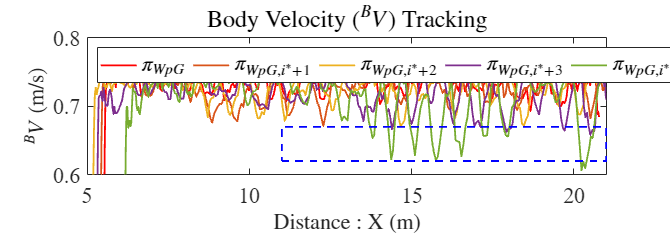


plot(curveA(1,:),0.75*ones(length(curveA(1,:)),1),'--k','LineWidth',1.5)

% Add a blue dotted rectangle
rectangle('Position', [11, 0.62, 10, 0.05], 'EdgeColor', 'b', 'LineStyle', '--', 'LineWidth', 1.5);


legend('$ \pi_{WpG}$','$ \pi_{WpG,i^{*}+1}$','$ \pi_{WpG,i^{*}+2}$','$ \pi_{WpG,i^{*}+3}$','$ \pi_{WpG,i^{*}+4}$','Ref','Location','northwest','Orientation','horizontal','Interpreter','latex','FontSize',FS)
ylim([0.6,0.8])
xlim([5 21])
xlabel('Distance : X (m)','Interpreter','latex','FontSize',FS)
ylabel('${}^{B}V$ (m/s)','Interpreter','latex','FontSize',FS)

box on

%print(f1,'IdxErrVel','-depsc')


%figure
%subplot(2,1,2)
FS = 18;

f1 = figure('Position', [100, 100, 1000, 350],'color','w') % [left, bottom, width, height]

f1 =   Figure (48) with properties:

      Number: 48
        Name: ''
       Color: [1 1 1]
    Position: [100 100 1000 350]
       Units: 'pixels'

  Show all properties


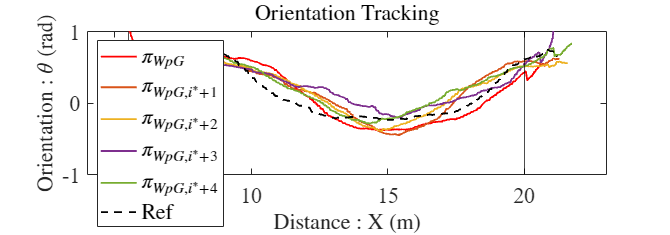

ax = gca;
ax.FontName= 'Times New Roman';
ax.FontSize = FS;

title('Orientation Tracking','FontWeight', 'bold','Interpreter','latex','FontSize',FS)
hold on

headingA = headingFromXY(curveA');
headingB = headingFromXY(curveB');
headingC = headingFromXY(curveC');
headingD = headingFromXY(curveD');
headingE = headingFromXY(curveE');
headingF = headingFromXY(curveF');

plot(curveB(1,:),headingB,'r','LineWidth',1.5)
plot(curveC(1,:),headingC,'color',colors(2,:),'LineWidth',1.5)
plot(curveD(1,:),headingD,'color',colors(3,:),'LineWidth',1.5)
plot(curveE(1,:),headingE,'color',colors(4,:),'LineWidth',1.5)
plot(curveF(1,:),headingF,'color',colors(5,:),'LineWidth',1.5)
plot(curveA(1,:),headingA,'--k','LineWidth',1.5)

xline(5.5,'k')
xline(20,'k')

legend('$ \pi_{WpG}$','$ \pi_{WpG,i^{*}+1}$','$ \pi_{WpG,i^{*}+2}$','$ \pi_{WpG,i^{*}+3}$','$ \pi_{WpG,i^{*}+4}$','Ref','Location','southwest','Orientation','vertical','Interpreter','latex','FontSize',FS)
ylim([-1,1])
xlim([4 23])
xlabel('Distance : X (m)','Interpreter','latex','FontSize',FS)
ylabel('Orientation : $\theta$ (rad)','Interpreter','latex','FontSize',FS)

% Adjust the width of the legend box to force line wrapping
%legend_position = get(legend_handle, 'Position');
%legend_position(3) = 1; % Adjust this value to control the width
%set(legend_handle, 'Position', legend_position);


box on


%print(f1,'IdxErrPose','-depsc')

[meanErrB, varErrB, errorsB] = compareCurves(curveA,curveB)

meanErrB = 0.7318

varErrB = 0.0925

errorsB =     0.8643    0.8532    0.8421    0.8311    0.8204    0.8110    0.8032    0.7978    0.7934    0.7906    0.7883    0.7864    0.7843    0.7835    0.7833    0.7793    0.7744    0.7701    0.7660    0.7612    0.7571    0.7537    0.7503    0.7468    0.7434    0.7403    0.7375    0.7347    0.7318    0.7296    0.7274    0.7256    0.7247    0.7241    0.7236    0.7236    0.7236    0.7242    0.7255    0.7268    0.7277    0.7280    0.7285    0.7294    0.7314    0.7344    0.7380    0.7425    0.7472    0.7524


[meanErrC, varErrC, errorsC] = compareCurves(curveA,curveC)

meanErrC = 0.4810

varErrC = 0.0543

errorsC =     0.0566    0.0504    0.0434    0.0369    0.0310    0.0261    0.0209    0.0150    0.0103    0.0103    0.0155    0.0230    0.0311    0.0396    0.0485    0.0570    0.0652    0.0735    0.0819    0.0890    0.0957    0.1019    0.1080    0.1143    0.1202    0.1264    0.1325    0.1389    0.1450    0.1515    0.1583    0.1652    0.1723    0.1797    0.1872    0.1949    0.2024    0.2097    0.2170    0.2261    0.2354    0.2439    0.2520    0.2606    0.2699    0.2795    0.2897    0.2998    0.3107    0.3217


[meanErrD, varErrD, errorsD] = compareCurves(curveA,curveD)

meanErrD = 0.7604

varErrD = 0.0584

errorsD =     0.6168    0.6217    0.6267    0.6317    0.6368    0.6414    0.6454    0.6497    0.6540    0.6584    0.6626    0.6663    0.6693    0.6726    0.6763    0.6808    0.6858    0.6910    0.6962    0.7006    0.7050    0.7093    0.7136    0.7177    0.7217    0.7257    0.7296    0.7334    0.7371    0.7407    0.7442    0.7475    0.7510    0.7545    0.7586    0.7628    0.7670    0.7712    0.7755    0.7806    0.7857    0.7903    0.7950    0.7999    0.8051    0.8102    0.8156    0.8212    0.8273    0.8336


[meanErrE, varErrE, errorsE] = compareCurves(curveA,curveE)

meanErrE = 1.0656

varErrE = 0.2628

errorsE =     1.3785    1.3783    1.3773    1.3743    1.3707    1.3674    1.3648    1.3634    1.3628    1.3624    1.3628    1.3633    1.3644    1.3656    1.3674    1.3694    1.3702    1.3710    1.3718    1.3722    1.3721    1.3723    1.3723    1.3725    1.3727    1.3729    1.3735    1.3741    1.3745    1.3750    1.3756    1.3762    1.3770    1.3779    1.3789    1.3800    1.3815    1.3826    1.3840    1.3863    1.3891    1.3919    1.3944    1.3972    1.4005    1.4036    1.4073    1.4114    1.4162    1.4213


[meanErrF, varErrF, errorsF] = compareCurves(curveA,curveF)

meanErrF = 1.4698

varErrF = 0.1225

errorsF =     1.2344    1.2358    1.2363    1.2374    1.2389    1.2394    1.2410    1.2442    1.2475    1.2515    1.2553    1.2595    1.2635    1.2670    1.2702    1.2730    1.2754    1.2777    1.2798    1.2806    1.2812    1.2814    1.2811    1.2805    1.2797    1.2790    1.2784    1.2782    1.2779    1.2778    1.2777    1.2782    1.2789    1.2793    1.2797    1.2799    1.2801    1.2798    1.2793    1.2799    1.2809    1.2814    1.2818    1.2825    1.2843    1.2863    1.2891    1.2917    1.2951    1.2987


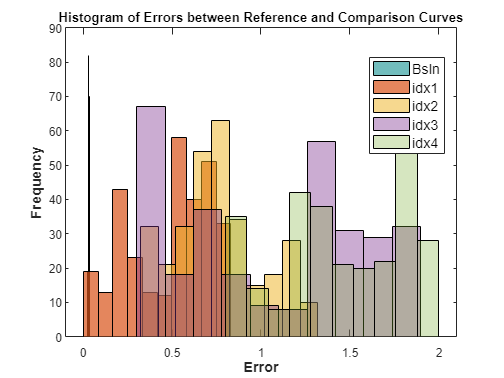



% Default MATLAB colors from the image you provided
colors = [
    0.4470 0.7410 0.7410;
    0.8500 0.3250 0.0980;
    0.9290 0.6940 0.1250;
    0.4940 0.1840 0.5560;
    0.4660 0.6740 0.1880;
    0.3010 0.7450 0.9330;
    0.6350 0.0780 0.1840;
];

% Plot the histogram of errors
figure;
hold on;

% Plot the first histogram with a solid color and edge
histogram(0.025+errorsB/d, 10, 'FaceColor', colors(1,:), 'EdgeColor', 'k', 'FaceAlpha', 1);

% Plot the remaining histograms with transparency and edges
histogram(errorsC, 10, 'FaceColor', colors(2,:), 'EdgeColor', 'k', 'FaceAlpha', 0.7);
histogram(errorsD, 10, 'FaceColor', colors(3,:), 'EdgeColor', 'k', 'FaceAlpha', 0.5);
histogram(errorsE, 10, 'FaceColor', colors(4,:), 'EdgeColor', 'k', 'FaceAlpha', 0.4);
histogram(errorsF, 10, 'FaceColor', colors(5,:), 'EdgeColor', 'k', 'FaceAlpha', 0.3);

% Add a legend to distinguish between the histograms
legend('Bsln', 'idx1', 'idx2', 'idx3', 'idx4', 'Location', 'best', 'FontSize', 12);

% Add title and labels with improved font size
title('Histogram of Errors between Reference and Comparison Curves', 'FontWeight', 'bold');
xlabel('Error', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Frequency', 'FontSize', 12, 'FontWeight', 'bold');

% Add grid for better readability
%grid on;

% Set axis properties for better visualization
%set(gca, 'FontSize', 12, 'LineWidth', 1.5);

% Adjust the layout to avoid overlapping
box on;
hold off;

[meanOrErrB, varOrErrB, OrerrorsB] = compareCurves([curveA(1,:);headingA'],[curveB(1,:);headingB'])

meanOrErrB = 0.2032

varOrErrB = 0.0034

OrerrorsB =     0.2817    0.2890    0.2689    0.2403    0.2064    0.1472    0.1094    0.0784    0.0571    0.0504    0.0554    0.0333    0.0356    0.0778    0.1456    0.2126    0.2047    0.2011    0.1969    0.1893    0.1900    0.1852    0.1856    0.1822    0.1826    0.1787    0.1763    0.1753    0.1751    0.1753    0.1743    0.1709    0.1746    0.1716    0.1711    0.1707    0.1699    0.1700    0.1840    0.1877    0.2045    0.2091    0.2128    0.2151    0.2166    0.2205    0.2240    0.2272    0.2269    0.2258


[meanOrErrC, varOrErrC, OrerrorsC] = compareCurves([curveA(1,:);headingA'],[curveC(1,:);headingC'])

meanOrErrC = 0.1601

varOrErrC = 0.0041

OrerrorsC =     0.1132    0.1277    0.1216    0.1103    0.0913    0.1130    0.1277    0.1373    0.1423    0.1497    0.1415    0.1589    0.1636    0.1509    0.1479    0.1206    0.1181    0.1063    0.1013    0.0954    0.0997    0.1016    0.1030    0.1044    0.1056    0.1093    0.1249    0.1273    0.1281    0.1269    0.1209    0.1327    0.1493    0.1433    0.1386    0.1526    0.1573    0.1700    0.1783    0.1930    0.1930    0.2033    0.2038    0.2094    0.2134    0.2213    0.2272    0.2254    0.2296    0.2230


[meanOrErrD, varOrErrD, OrerrorsD] = compareCurves([curveA(1,:);headingA'],[curveD(1,:);headingD'])

meanOrErrD = 0.2611

varOrErrD = 0.0023

OrerrorsD =     0.3367    0.3350    0.3245    0.3236    0.3057    0.3055    0.3054    0.3057    0.3039    0.2972    0.2868    0.2881    0.2946    0.3007    0.3213    0.3047    0.3009    0.2964    0.2958    0.2906    0.2912    0.2901    0.2899    0.2890    0.2874    0.2872    0.2880    0.2881    0.2868    0.2855    0.2857    0.2879    0.2933    0.2917    0.2850    0.2861    0.2891    0.2928    0.2951    0.2973    0.2970    0.2980    0.2994    0.3030    0.3075    0.3206    0.3253    0.3382    0.3412    0.3490


[meanOrErrE, varOrErrE, OrerrorsE] = compareCurves([curveA(1,:);headingA'],[curveE(1,:);headingE'])

meanOrErrE = 0.2013

varOrErrE = 0.0051

OrerrorsE =     0.1390    0.1503    0.1832    0.1964    0.1982    0.1882    0.1815    0.1834    0.1880    0.1933    0.1965    0.2029    0.2075    0.2088    0.2198    0.2119    0.2112    0.2107    0.2110    0.2104    0.2122    0.2124    0.2143    0.2141    0.2140    0.2144    0.2145    0.2146    0.2148    0.2141    0.2149    0.2140    0.2171    0.2140    0.2147    0.2167    0.2195    0.2225    0.2220    0.2246    0.2322    0.2408    0.2504    0.2596    0.2688    0.2831    0.2871    0.2921    0.2953    0.2993


[meanOrErrF, varOrErrF, OrerrorsF] = compareCurves([curveA(1,:);headingA'],[curveF(1,:);headingF'])

meanOrErrF = 0.7750

varOrErrF = 0.0015

OrerrorsF =     0.7258    0.7201    0.7128    0.7070    0.7131    0.7101    0.7114    0.7091    0.7073    0.7062    0.7082    0.7093    0.7067    0.7033    0.7032    0.7077    0.7093    0.7101    0.7101    0.7118    0.7113    0.7114    0.7097    0.7098    0.7095    0.7091    0.7085    0.7082    0.7075    0.7076    0.7086    0.7098    0.7140    0.7146    0.7165    0.7169    0.7184    0.7202    0.7230    0.7238    0.7252    0.7278    0.7288    0.7297    0.7288    0.7307    0.7309    0.7332    0.7339    0.7346


% Default MATLAB colors from the image you provided
colors = [
    1 0 0;
    0.9290 0.6940 0.1250;
    0.4940 0.1840 0.5560;
    0.4660 0.6740 0.1880;
    0.3010 0.7450 0.9330;
];

% Plot the histogram of errors
f1 = figure('color','white');
FS = 16

FS = 16

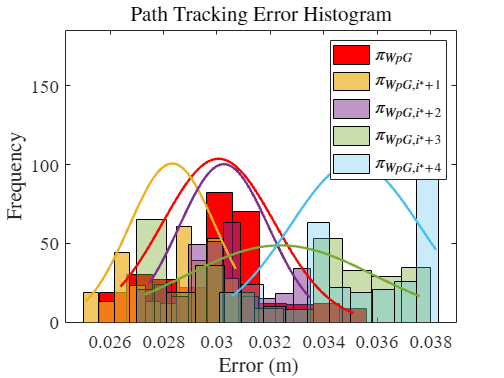

ax = gca;
ax.FontName= 'Times New Roman';
ax.FontSize = FS;


hold on;

% Plot histograms
histogram(0.025+ errorsB/d, 10, 'FaceColor', colors(1,:), 'EdgeColor', 'k', 'FaceAlpha', 1);
histogram(0.025+ errorsC/d, 10, 'FaceColor', colors(2,:), 'EdgeColor', 'k', 'FaceAlpha', 0.7);
histogram(0.025+ errorsD/d, 10, 'FaceColor', colors(3,:), 'EdgeColor', 'k', 'FaceAlpha', 0.5);
histogram(0.025+ errorsE/d, 10, 'FaceColor', colors(4,:), 'EdgeColor', 'k', 'FaceAlpha', 0.4);
histogram(0.025+ errorsF/d, 10, 'FaceColor', colors(5,:), 'EdgeColor', 'k', 'FaceAlpha', 0.3);

% Define and plot Gaussian curves
errorSets = {0.025 + (errorsB/d), 0.025 + (errorsC/d), 0.025 + (errorsD/d), 0.025 + (errorsE/d), 0.025 + (errorsF/d)};
for i = 1:length(errorSets)
    % Fit a normal distribution to the data
    pd = fitdist(errorSets{i}', 'Normal');
    
    % Define the range for the x-axis
    x_values = linspace(min(errorSets{i}), max(errorSets{i}), 100);
    
    % Compute the corresponding y-values of the Gaussian curve
    y_values = pdf(pd, x_values);
    
    % Scale the Gaussian curve to match the histogram
    y_values = y_values * max(histcounts(errorSets{i}, 10));
    
    % Plot the Gaussian curve
    plot(x_values, y_values/1.5e2, 'Color', colors(i,:), 'LineWidth', 2);
end



title('Path Tracking Error Histogram','FontWeight', 'bold','Interpreter','latex');
xlabel('Error (m) ','FontWeight', 'bold','Interpreter','latex');
ylabel('Frequency','FontWeight', 'bold','Interpreter','latex');
box on
legend('$ \pi_{WpG}$','$ \pi_{WpG,i^{*}+1}$','$ \pi_{WpG,i^{*}+2}$','$ \pi_{WpG,i^{*}+3}$','$ \pi_{WpG,i^{*}+4}$','Location','northeast','Orientation','vertical','Interpreter','latex','FontSize',FS)
% Remove the grid for a cleaner look
grid off;

% Set axis properties for better visualization
%set(gca, 'FontSize', 12, 'LineWidth', 1.5);

% Adjust the layout to avoid overlapping
box on;
hold off;
ylim([0 185])


%print(f1,'IdxErrHist','-depsc')


figure
hold on
i = 2
k_t = find(sensor(i).data.joint_states(1,:)>0);
plot(movmean(TSyn(i).data.odom_VelLinX(k_t),10))
%plot(movmean(TSyn(3).data.odom_VelLinX(:),10))

figure
hold on
i = 2
k_t = find(sensor(i).data.joint_states(1,:)>0);
plot(movmean(-1*TSyn(i).data.IMU_fil_AngZ(k_t),10))
%plot(movmean(-1*TSyn(3).data.IMU_fil_AngZ(:),1))

start = 0;
%stop = 
figure
hold on
title('Combined curves')

for i = [1,5,6,7,8]
    k_t = find(sensor(i).data.joint_states(1,:)>0);
    %A = mean([TSyn(i).data.enu_x_head(k_t);TSyn(i).data.enu_x_head(k_t)]);
    A = [TSyn(i).data.pos_x(k_t)];
    %B = mean([TSyn(i).data.enu_y_head(k_t);TSyn(i).data.enu_y_head(k_t)]);
    B = [TSyn(i).data.pos_y(k_t)];
    idx = 1:length(A);
    A_ = movmean(A(idx),50);
    B_ = movmean(B(idx),50);
    %plot((0.5*rand-0.5)*0.005*length(A_) + (A_ - A_(1)),(0.5*rand-0.5)*0.00*length(B_) + (B_ - B_(1)))
    plot(A_,B_)
end

legend('Bsln','idx1','idx2','idx3','idx4')
xlabel('X (m)')
ylabel('X (m)')


start = 0;
%stop = 
figure
hold on
title('Linear Velocities')

for i = [1,5,6,7,8]
    k_t = find(sensor(i).data.joint_states(1,:)>0);
    %A = [TSyn(i).data.enu_x(k_t));
    %B = mean([TSyn(i).data.enu_y(k_t);TSyn(i).data.enu_y_head(k_t)]);
    idx = 1:length(A);
    plot(TSyn(i).data.odom_VelLinX(k_t))
    mean(TSyn(i).data.odom_VelLinX(k_t))
end

legend('Bsln','idx1','idx2','idx3','idx4')
xlabel('X (m)')
ylabel('X (m)')


function [meanError, varianceError, errors] = compareCurves(referenceCurve, comparisonCurve)
    % Function to calculate the signed error between two curves based on arc length parameterization
    % Inputs:
    %   referenceCurve: 2xm matrix of path points for the reference curve
    %   comparisonCurve: 2xn matrix of path points for the comparison curve
    % Outputs:
    %   meanError: mean of the errors between the two curves
    %   varianceError: variance of the errors between the two curves
    %   errors: array of signed errors between the two curves for further analysis

    % Ensure the curves are 2xm and 2xn matrices
    assert(size(referenceCurve, 1) == 2, 'Reference curve must be a 2xm matrix');
    assert(size(comparisonCurve, 1) == 2, 'Comparison curve must be a 2xn matrix');

    % Arc length parameterization for the reference curve
    refDiffs = diff(referenceCurve, 1, 2);
    refArcLengths = [0, cumsum(sqrt(sum(refDiffs.^2, 1)))];

    % Arc length parameterization for the comparison curve
    compDiffs = diff(comparisonCurve, 1, 2);
    compArcLengths = [0, cumsum(sqrt(sum(compDiffs.^2, 1)))];

    % Determine a common arc length scale for interpolation
    commonArcLengths = linspace(0, min([refArcLengths(end), compArcLengths(end)]), max(length(refArcLengths), length(compArcLengths)));

    % Interpolate both curves to the common arc length scale
    interpolatedRefCurve = interp1(refArcLengths, referenceCurve', commonArcLengths, 'linear', 'extrap')';
    interpolatedCompCurve = interp1(compArcLengths, comparisonCurve', commonArcLengths, 'linear', 'extrap')';

    % Calculate the signed error between the reference curve and the interpolated comparison curve
    errors = interpolatedCompCurve - interpolatedRefCurve; % This gives a 2xn matrix of errors

    % Project errors onto the direction of the curve, if needed, or consider only one dimension
    % Here we assume you want to analyze the error in the Y direction (vertical error):
    %signedErrors = errors(2, :); % Only considering the Y difference for histogram
    signedErrors = sqrt(errors(1,:).^2+errors(2,:).^2);

    % Calculate mean and variance of the signed errors
    if isempty(signedErrors)
        meanError = NaN;
        varianceError = NaN;
        warning('All error values resulted in NaN after interpolation.');
    else
        meanError = mean(signedErrors);
        varianceError = var(signedErrors);
    end
    
    % Return signed errors for histogram plotting
    errors = signedErrors;
end
